8.1 （按键拨号）实时脚本

由张志涌编写、修改于 2023.1。

拨号音的合成

s = '6';		%以s为字符'6'举例
switch s
case '*', k = 4; j = 1;
case '0', k = 4; j = 2;
case '#', k = 4; j = 3;
    otherwise
d = s-'0'; j = mod(d-1,3)+1; k = (d-j)/3+1;
end
k,j

k = 2

j = 3

fr=[697,770,852,941];
fc=[1209,1336,1477];
Fs = 32768;
t = 0:1/Fs:0.25;
y1 = sin(2*pi*fr(k)*t);
y2 = sin(2*pi*fc(j)*t);
y = (y1 + y2)/2;
sound(y,Fs)

整段录音的FFT

load touchtone
y

y = 包含以下字段的 struct :
    sig: [-1 -1 -1 -1 -1 0 1 0 0 0 -2 3 0 0 0 1 -2 1 -2 -1 -3 -2 -2 -3 -5 1 -2 -1 -1 -1 0 -1 -2 -2 -1 -3 -1 0 1 -1 -1 0 -2 1 -2 1 -1 0 0 -1 0 2 2 3 2 3 2 1 1 1 2 1 2 0 1 -2 -1 -1 -3 -2 0 -3 -1 -2 -1 -1 1 0 1 0 2 2 1 1 0 -3 -2 -2 -2 0 0 1 -1 1 -2 -2 0 … ]
     fs: 8192


max(y.sig),min(y.sig)

ans = int8
122

ans = int8
-121

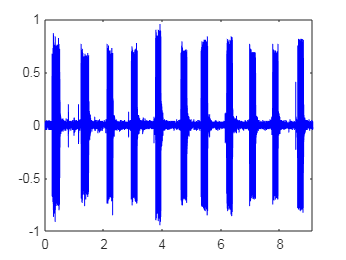


Fs = y.fs;
y = double(y.sig)/128;
n = length(y);
t = (0: n-1)/Fs;
plot(t,y,'b'); axis([0,t(end),-1,1])

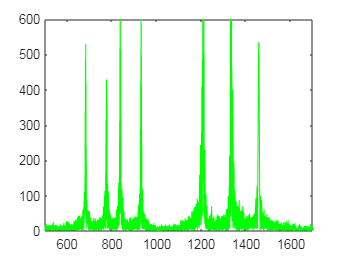

p = abs(fft(y));
f = (0:n-1)*(Fs/n);
plot(f,p,'g');
axis([500 1700 0 600])

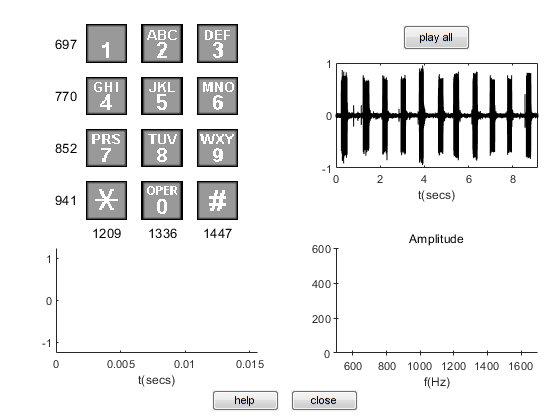

figure
touchtone	